MAIN_DIR = "C:\Users\gridd\OneDrive\Рабочий стол\ITMO\fourier_labs\Lab6\image\"

MAIN_DIR = "C:\Users\gridd\OneDrive\Рабочий стол\ITMO\fourier_labs\Lab6\image\"

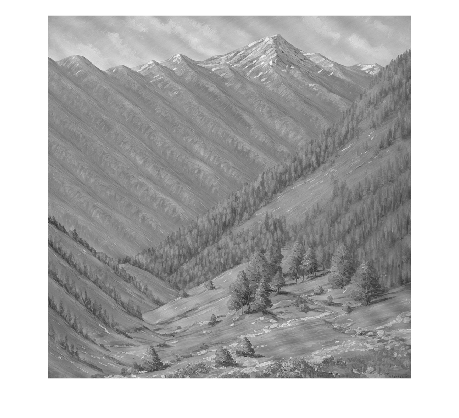

img = im2gray(imread(MAIN_DIR + "\part-1\filtered_image.png"));
imshow(img);

imwrite(img, MAIN_DIR + "grayImg.png");
n1 = 3, n2 = 21, n3=33; 

n1 = 3

n2 = 21

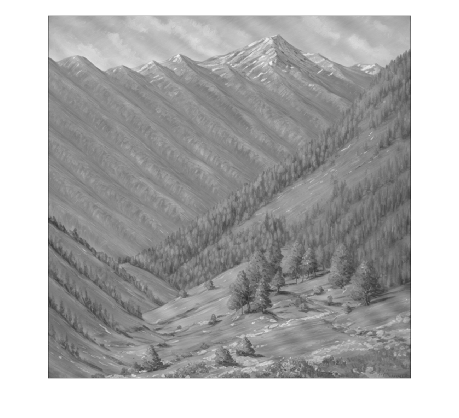

block_blur1 = ones(n1)/n1^2.;
block_blur2 = ones(n2)/n2^2.;
block_blur3 = ones(n3)/n3^2.;
gauss_blur1 = zeros(n1);
gauss_blur2 = zeros(n2);
gauss_blur3 = zeros(n3);

for x = 1:1:n1
    for y = 1:1:n1
        gauss_blur1(x,y) = func(n1,x,y);
    end
end

for x = 1:1:n2
    for y = 1:1:n2
        gauss_blur2(x,y) = func(n2,x,y);
    end
end

for x = 1:1:n3
    for y = 1:1:n3
        gauss_blur3(x,y) = func(n3,x,y);
    end
end

gauss_blur1 = gauss_blur1/sum(gauss_blur1, "all");
gauss_blur2 = gauss_blur2/sum(gauss_blur2, "all");
gauss_blur3 = gauss_blur3/sum(gauss_blur3, "all");

img_block_blur1 = cast(conv2(img, block_blur1), "uint8");
img_block_blur2 = cast(conv2(img, block_blur2), "uint8");
img_block_blur3 = cast(conv2(img, block_blur3), "uint8");

imshow(img_block_blur1)

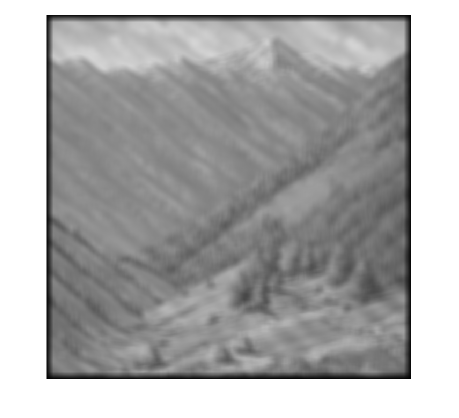

imwrite(img_block_blur1, MAIN_DIR + "img_block_blur1.png");
imshow(img_block_blur2);

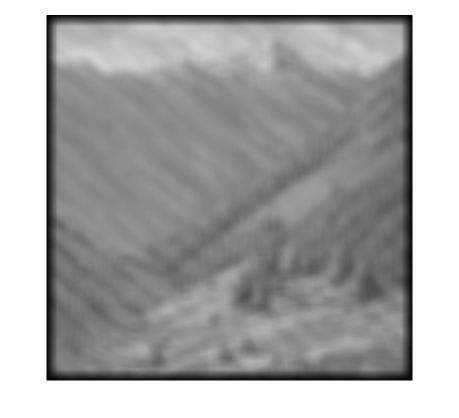

imwrite(img_block_blur2, MAIN_DIR + "img_block_blur2.png");
imshow(img_block_blur3)

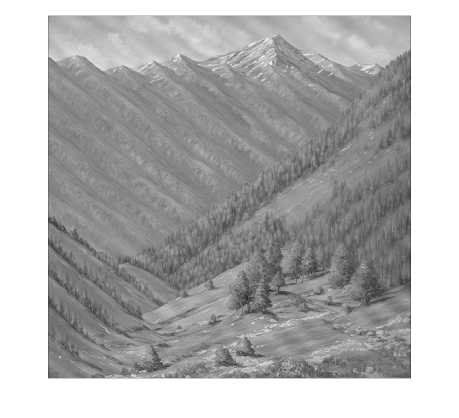

imwrite(img_block_blur3, MAIN_DIR + "img_block_blur3.png");

img_gauss_blur1 = cast(conv2(img, gauss_blur1), "uint8");
img_gauss_blur2 = cast(conv2(img, gauss_blur2), "uint8");
img_gauss_blur3 = cast(conv2(img, gauss_blur3), "uint8");

imshow(img_gauss_blur1);

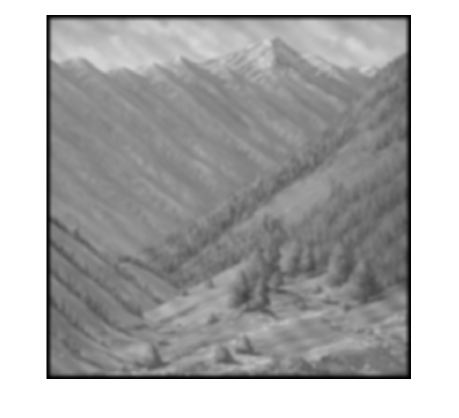

imwrite(img_gauss_blur1, MAIN_DIR + "img_gauss_blur1.png");
imshow(img_gauss_blur2);

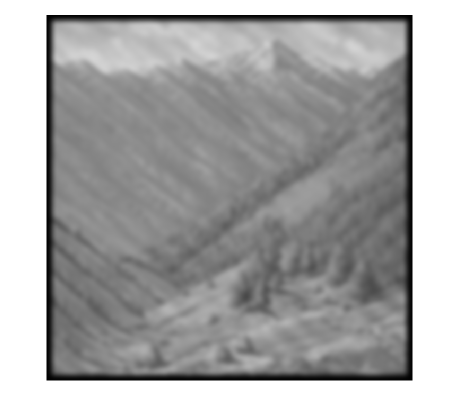

imwrite(img_gauss_blur2, MAIN_DIR + "img_gauss_blur2.png");
imshow(img_gauss_blur3);

imwrite(img_gauss_blur3, MAIN_DIR + "img_gauss_blur3.png");

img_conv1 = cast(conv_pad(img, gauss_blur1), "uint8")

img_conv1 = 1026×1026 uint8 matrix
     7    26    33    32    33    33    33    33    33    33    33    33    34    35    35    35    34    35    35    36    36    36    36    36    36    36    36    37    37    37    37    37    38    38    38    38    38    38    38    38    39    39    39    39    39    39    39    39    39    39
    26    96   121   121   122   122   122   123   124   124   124   125   126   128   129   129   129   129   131   132   132   132   133   133   134   134   135   135   136   137   138   138   139   140   141   141   141   142   142   143   143   144   144   145   145   145   145   145   146   146
    33   122   155   154   154   154   156   158   159   159   158   159   160   163   164   165   165   165   166   167   167   168   170   170   169   169   170   171   173   174   174   175   176   177   177   177   178   179   180   181   182   182   183   183   183   183   184   185   186   185
    33   123   156   154   153   154   156   158   159   159  

img_conv2 = cast(conv_pad(img, gauss_blur2), "uint8")

img_conv2 = 1044×1044 uint8 matrix
    0    0    0    0    0    0    0    1    1    1    1    1    1    1    1    1    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2
    0    0    0    0    0    1    1    1    2    2    2    3    3    3    3    4    4    4    4    4    4    4    4    4    4    4    4    4    4    4    5    5    5    5    5    5    5    5    5    5    5    5    5    5    5    5    5    5    5    5
    0    0    0    1    1    1    2    2    3    4    4    5    5    6    6    7    7    7    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    9    9    9    9    9    9    9    9    9    9    9    9    9
    0    0    1    1    1    2    3    4    5    6    7    8    9   10   10   11   12   12   12   13   13   13   13   13   13   13   13   13   13   13   13   14   14   14   14   14   14   14   14   14   14   14  

img_conv3 = cast(conv_pad(img, gauss_blur3), "uint8")

img_conv3 = 1056×1056 uint8 matrix
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1
    0    0    0    0    0    0    0    0    0    0    1    1    1    1    1    1    1    1    1    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    2    3    3    3    3    3    3    3    3    3    3
    0    0    0    0    0    0    0    0    1    1    1    1    1    1    2    2    2    2    2    3    3    3    3    3    4    4    4    4    4    4    4    4    4    4    4    4    4    4    4    4    4    4    4    4    4    4    4    4    4    4
    0    0    0    0    0    0    1    1    1    1    1    2    2    2    3    3    3    3    4    4    4    5    5    5    5    6    6    6    6    6    6    6    6    6    6    6    6    6    6    7    7    7  


imshow(img_conv1);

imwrite(img_conv1, MAIN_DIR + "img_conv1.png");
imshow(img_conv2);

imwrite(img_conv2, MAIN_DIR + "img_conv2.png");
imshow(img_conv3)

imwrite(img_conv3, MAIN_DIR + "img_conv3.png");

function y = func(n,x,y)
    y = exp((-9/n^2)*((x-(n+1)/2)^2+(y-(n+1)/2)^2));
end

function y = conv_pad(img, kernel)
    h = height(img);
    w = width(img);
    fourier_transform_img = fftshift(fft2(img, h+height(kernel)-1,w+width(kernel)-1));
    fourier_transform_kernel = fftshift(fft2(kernel, h+height(kernel)-1,w+width(kernel)-1)); 
    fft_conv = fourier_transform_img.*fourier_transform_kernel;
    y = ifft2(ifftshift(fft_conv));
end